clear all;
clc;
cstr_global;

global Wc u1 u2
sample_T = 0.1;

n_op = 2;
n_ip = 2;
n_st = 2;
n_d = 2;
N_samples = 500;

G_Ko = 1.0e10;
G_E = 8330.1;
G_V = 1.0;
G_Cp = 1.0;
G_rho = 1e6;
G_delH = 1.3e8;
G_Cpc = 1.0;
G_rhoc = 1e6;
G_a = 1.678e6;
G_b = 0.5;
G_To = 323.0;

state_sigma = [0.001 0.5];
meas_sigma = [0.001 0.5];

u_ss = [1 15]';
Uk(:,1) = u_ss;

u1 = 1;
u2 = 15;
C =[1 0;0 1];

Cao = 2.0;
Tcin = 92 + 273;
Wc = [Cao; Tcin];

for i = 1:1:500
    wk(1,i) = state_sigma(1)*randn;
    wk(2,i) = state_sigma(2)*randn;
end

for i = 1:1:500
    vk(1,i) = meas_sigma(1)*randn;
    vk(2,i) = meas_sigma(2)*randn;
end

x_initial = [0.5 400]';

for i = 1:1:500
    [T,Xj] = ode45('cstr_model',[0 sample_T],x_initial);
    X_state(i,:) = Xj(end,:);
    x_initial = Xj(end,:)';
end

figure(1)
subplot(211)
plot(1:500,X_state(:,1),'b')
ylabel('Ca')

subplot(212)
plot(1:500,X_state(:,2),'b')
xlabel('Sampling Instant')
ylabel('T')

X_steady_state = X_state(end,:);

u1_flow = 1 + idinput(500,'PRBS',[0 0.166],[-0.05 0.05]);

u2_temp = 15 + idinput(500,'PRBS',[0 0.166],[-0.75 0.75]);

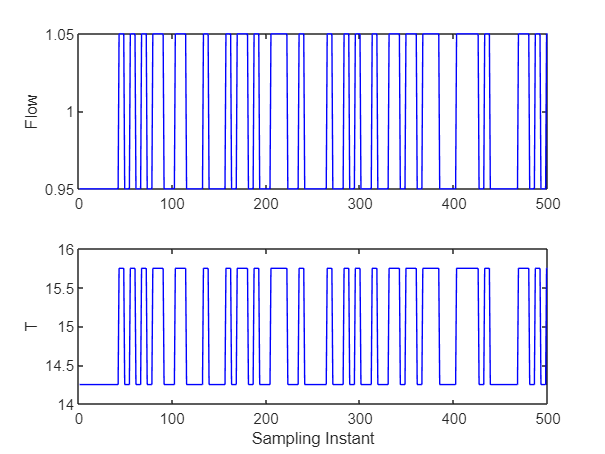


figure(2)
subplot(211)
plot(1:500,u1_flow(:,1),'b')
ylabel('Flow')

subplot(212)
plot(1:500,u2_temp(:,1),'b')
xlabel('Sampling Instant')
ylabel('T')

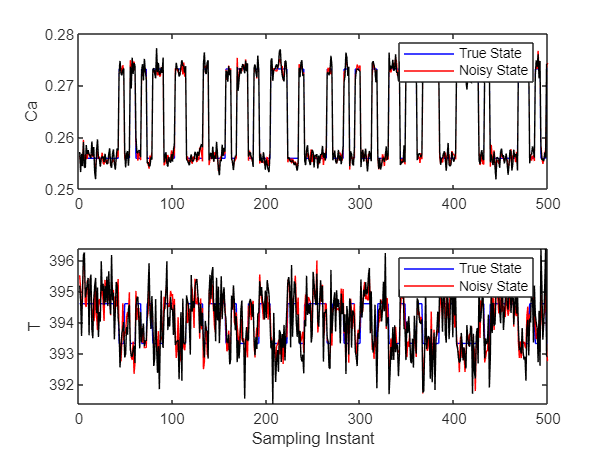


x_initial2 = X_steady_state;
for i = 1:1:N_samples
    u1 = u1_flow(i,1);
    u2 = u2_temp(i,1);
    [T,XM] = ode45('cstr_model',[0 sample_T],x_initial2);
    X_new_state(i,:) = XM(end,:);
    X_noisy_state(i,:) = X_new_state(i,:) + wk(:,i)';
    Yk(:,i) = C*X_noisy_state(i,:)' + vk(:,i);
end

figure(1)
subplot(211)
plot(1:500,X_new_state(:,1),'b', 1:500, X_noisy_state(:,1),'r', 1:500, Yk(1,:)','k')
ylabel('Ca')
legend('True State', 'Noisy State')

subplot(212)
plot(1:500,X_new_state(:,2),'b', 1:500, X_noisy_state(:,2),'r',1:500, Yk(2,:)','k')
xlabel('Sampling Instant')
ylabel('T')
legend('True State', 'Noisy State')